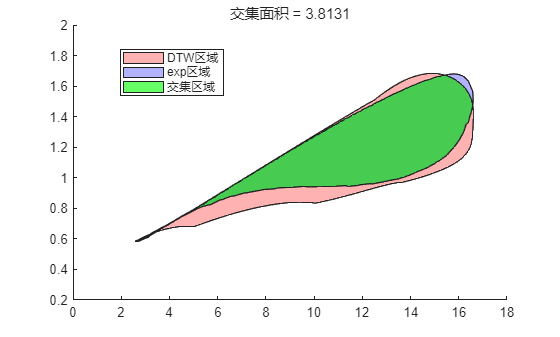

clear
load("C:\Users\Administrator\Desktop\optimal\optimal_compress_wes@are\compare_DTW_ARE_MSE\9.6±7_re2e6_2.4\data_collection_DTW.mat")

% 构造多边形区域
pg1 = polyshape(DTW_data(:,1), DTW_data(:,2));
pg2 = polyshape(exp_data(:,1), exp_data(:,2));

% 求交集
pg_inter = intersect(pg1, pg2);

% 求交集面积
A_inter = area(pg_inter);

figure;
plot(pg1, 'FaceColor', 'red', 'FaceAlpha', 0.3);
hold on;
plot(pg2, 'FaceColor', 'blue', 'FaceAlpha', 0.3);
plot(pg_inter, 'FaceColor', 'green', 'FaceAlpha', 0.6);
ylim([0.2 2])
legend('DTW区域', 'exp区域', '交集区域');
title(['交集面积 = ', num2str(A_inter)]);